Test 2 - Balahura Vlad grupa 231/1

**Problema 2**.  Sa se aproximeze functia: $\[
f : [-\pi,\pi] \to \mathbb{R}, \qquad
f(x)=x+\sin\left(x^{2}\right)
\]$

(a) Folosind toate cele patru tipuri de spline, noduri echidistante si noduri Cebısev de speta I, n = 10

f = @(x) x + cos(x.^2);
df = @(x) 1 - 2.*x.*sin(x.^2); 
d2f = @(x) -2.*sin(x.^2) - 4.*(x.^2).*cos(x.^2);

n = 10;
a = -pi; 
b = pi;

xx = linspace(a, b, 500);
yy_exact = f(xx);

x_echid = linspace(a, b, n);
y_echid = f(x_echid);

x_cheb1 = CebisevI(a, b, n);
y_cheb1 = f(x_cheb1);

der1_echid = [df(x_echid(1)), df(x_echid(end))];
der2_echid = [d2f(x_echid(1)), d2f(x_echid(end))];


S_comp_eq = evalsplineCubic(x_echid, y_echid, 'complete', der1_echid, xx);
S_nat_eq  = evalsplineCubic(x_echid, y_echid, 'naturale', [], xx);
S_der2_eq = evalsplineCubic(x_echid, y_echid, 'derivate2', der2_echid, xx);
S_deB_eq  = evalsplineCubic(x_echid, y_echid, 'deBoor', [], xx);

Reprezentam grafic rezultatele separat, functie si axproximanta atat in cazul nodurilor echidistante cat si a lor Cebisev I

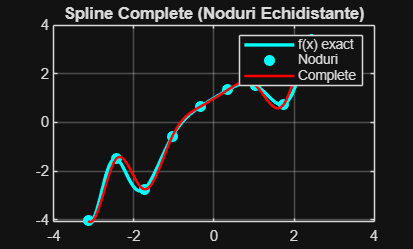

figure('Name', 'Spline Complete - Echidistante');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_echid, y_echid, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_comp_eq, 'r-', 'LineWidth', 1.5);
title('Spline Complete (Noduri Echidistante)');
legend('f(x) exact', 'Noduri', 'Complete'); grid on; hold off;

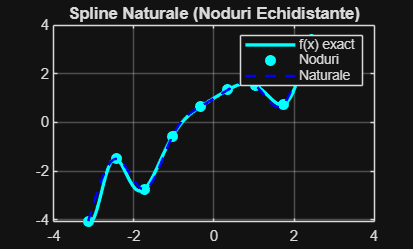



figure('Name', 'Spline Naturale - Echidistante');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_echid, y_echid, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_nat_eq, 'b--', 'LineWidth', 1.5);
title('Spline Naturale (Noduri Echidistante)');
legend('f(x) exact', 'Noduri', 'Naturale'); grid on; hold off;

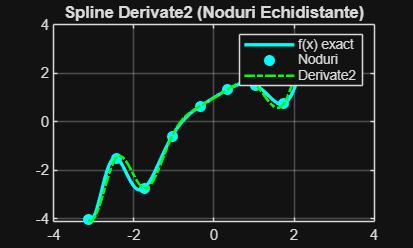


figure('Name', 'Spline Derivate2 - Echidistante');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_echid, y_echid, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_der2_eq, 'g-.', 'LineWidth', 1.5);
title('Spline Derivate2 (Noduri Echidistante)');
legend('f(x) exact', 'Noduri', 'Derivate2'); grid on; hold off;

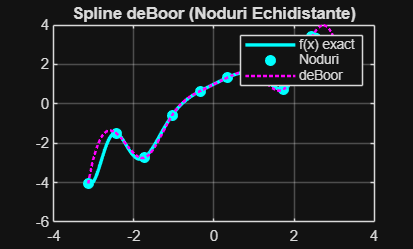



figure('Name', 'Spline deBoor - Echidistante');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_echid, y_echid, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_deB_eq, 'm:', 'LineWidth', 1.5);
title('Spline deBoor (Noduri Echidistante)');
legend('f(x) exact', 'Noduri', 'deBoor'); grid on; hold off;

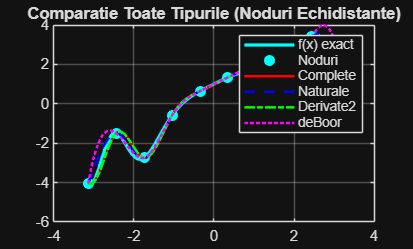



figure('Name', 'Toate Spline-urile - Echidistante');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_echid, y_echid, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_comp_eq, 'r-', 'LineWidth', 1.5);
plot(xx, S_nat_eq, 'b--', 'LineWidth', 1.5);
plot(xx, S_der2_eq, 'g-.', 'LineWidth', 1.5);
plot(xx, S_deB_eq, 'm:', 'LineWidth', 1.5);
title('Comparatie Toate Tipurile (Noduri Echidistante)');
legend('f(x) exact', 'Noduri', 'Complete', 'Naturale', 'Derivate2', 'deBoor'); grid on; hold off;

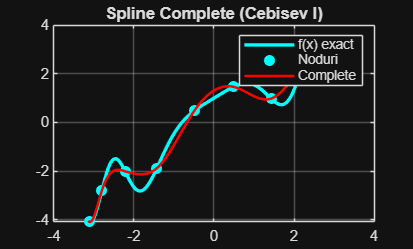




der1_cheb = [df(x_cheb1(1)), df(x_cheb1(end))];
der2_cheb = [d2f(x_cheb1(1)), d2f(x_cheb1(end))];

S_comp_ch = evalsplineCubic(x_cheb1, y_cheb1, 'complete', der1_cheb, xx);
S_nat_ch  = evalsplineCubic(x_cheb1, y_cheb1, 'naturale', [], xx);
S_der2_ch = evalsplineCubic(x_cheb1, y_cheb1, 'derivate2', der2_cheb, xx);
S_deB_ch  = evalsplineCubic(x_cheb1, y_cheb1, 'deBoor', [], xx);


figure('Name', 'Spline Complete - Cebisev I');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_cheb1, y_cheb1, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_comp_ch, 'r-', 'LineWidth', 1.5);
title('Spline Complete (Cebisev I)');
legend('f(x) exact', 'Noduri', 'Complete'); grid on; hold off;

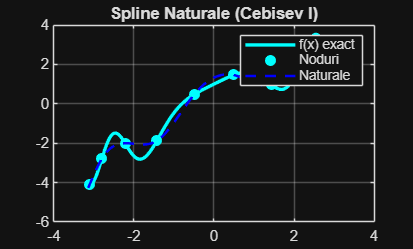



figure('Name', 'Spline Naturale - Cebisev I');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_cheb1, y_cheb1, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_nat_ch, 'b--', 'LineWidth', 1.5);
title('Spline Naturale (Cebisev I)');
legend('f(x) exact', 'Noduri', 'Naturale'); grid on; hold off;

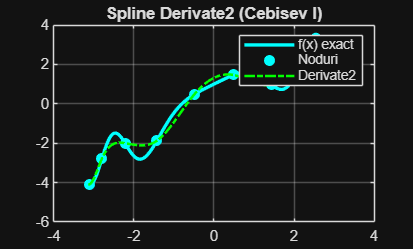



figure('Name', 'Spline Derivate2 - Cebisev I');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_cheb1, y_cheb1, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_der2_ch, 'g-.', 'LineWidth', 1.5);
title('Spline Derivate2 (Cebisev I)');
legend('f(x) exact', 'Noduri', 'Derivate2'); grid on; hold off;

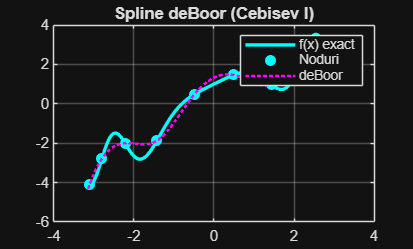



figure('Name', 'Spline deBoor - Cebisev I');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_cheb1, y_cheb1, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_deB_ch, 'm:', 'LineWidth', 1.5);
title('Spline deBoor (Cebisev I)');
legend('f(x) exact', 'Noduri', 'deBoor'); grid on; hold off;

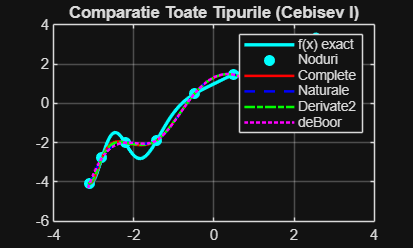



figure('Name', 'Toate Spline-urile - Cebisev I');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_cheb1, y_cheb1, 'co', 'MarkerFaceColor', 'c');
plot(xx, S_comp_ch, 'r-', 'LineWidth', 1.5);
plot(xx, S_nat_ch, 'b--', 'LineWidth', 1.5);
plot(xx, S_der2_ch, 'g-.', 'LineWidth', 1.5);
plot(xx, S_deB_ch, 'm:', 'LineWidth', 1.5);
title('Comparatie Toate Tipurile (Cebisev I)');
legend('f(x) exact', 'Noduri', 'Complete', 'Naturale', 'Derivate2', 'deBoor'); grid on; hold off;

b)  Folosind metoda celor mai mici patrate discretasi noduri Cebısev de speta II, n = 10.

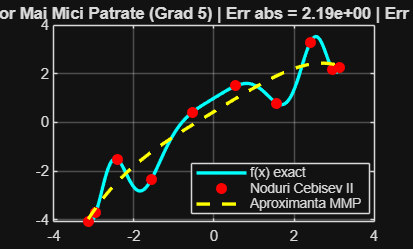

x_cheb2 = CebisevII(a, b, n)';
y_cheb2 = f(x_cheb2);

grad_polinom = 5; 
m_cols = grad_polinom + 1;

A_vandermonde = zeros(n, m_cols);
for j = 1:m_cols
    A_vandermonde(:, j) = x_cheb2 .^ (j - 1);
end

[c_mmp, err_mmp, err_rel_mmp] = linsys2(A_vandermonde, y_cheb2);

y_mmp = zeros(size(xx));
for j = 1:m_cols
    y_mmp = y_mmp + c_mmp(j) .* (xx .^ (j - 1));
end

figure('Name', 'CMMMP Discreta - Cebisev II');
plot(xx, yy_exact, 'c-', 'LineWidth', 2); hold on;
plot(x_cheb2, y_cheb2, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
plot(xx, y_mmp, 'y--', 'LineWidth', 2);

title(sprintf('Metoda Celor Mai Mici Patrate (Grad %d) | Err abs = %.2e | Err rel = %.2e',       grad_polinom, err_mmp, err_rel_mmp));
legend('f(x) exact', 'Noduri Cebisev II', 'Aproximanta MMP', 'Location', 'best');
grid on; hold off;

Calculam nodurile pe intervalul standard [-1,1] , dupa formula

    
$$$$t_k = \cos\left(\frac{2k+1}{2m}\pi\right), \quad k = 0, 1, \dots, m-1$$$$


Iar apoi aplicam o translatie in intervalul [a,b]


$$$$x_k = \frac{a+b}{2} + \frac{b-a}{2} t_k$$$$


function x = CebisevI(a, b, m)
j = 0:m-1;
x = cos((2*j + 1) * pi / (2 * m));
x = (a + b) / 2 + (b - a) / 2 * x;
x = sort(x); 
end

Calculăm nodurile Cebîșev de ordinul al doilea pe intervalul standard $\([-1,1]\)$ folosind relația


$$\[
x_j=\cos\left(\frac{j\pi}{m-1}\right), \qquad j=0,\dots,m-1.
\]$$


Apoi aplicăm transformarea afină


$$\[
x_j = \frac{a+b}{2}+\frac{b-a}{2}x_j,
\]$$


pentru a transpune nodurile în intervalul$ \([a,b]\)$. La final, nodurile sunt ordonate crescător.

function x = CebisevII(a, b, m)
j = 0:m-1;
x = cos(j * pi / (m - 1));
x = (a + b) / 2 + (b - a) / 2 * x;
x = sort(x);
end

Funcția rezolvă problema celor mai mici pătrate asociată sistemului supradeterminat$$Ac \approx f$$, utilizând factorizarea QR $$A = QR$$ , unde$$Q \in \mathbb{R}^{n \times m}$$ are coloane ortonormate, iar$$R \in \mathbb{R}^{m \times m}$$ este superior triunghiulară.Soluția se obține prin rezolvarea sistemului$$$Rc = Q^T f,$$$iar erorile returnate sunt:$$$\text{err} = \|Ac - f\|_2,$$$reprezentând norma reziduului absolut, și$$$\text{err\_rel} = \frac{\|Ac - f\|_2}{\|f\|_2},$$$reprezentând eroarea relativă a aproximării.

function [c, err, err_rel] = linsys2(A, f)
    [Q, R] = qr(A, 0);
    c = R \ (Q' * f);
    err = norm(A * c - f);
    err_rel = err / norm(f);
end

Functia evaluează spline-ul cubic în punctele x folosind coeficienții


$$\[
S_i(x)=c_{i,1}+c_{i,2}(x-x_i)+c_{i,3}(x-x_i)^2+c_{i,4}(x-x_i)^3.
\]$$


Pentru fiecare punct$ \(x\)$, se identifică intervalul$ \([x_i,x_{i+1}]\) $corespunzător și se calculează baza locală$ \(t=x-x_i\)$. Valoarea finală $\(S(x)\) $este obținută prin schema Horner pentru evaluarea polinomului cubic pe fiecare subinterval.

function S = evalsplineCubic(nodes, values, type, der_values, x)
    c = splineCubic(nodes, values, type, der_values);
    S = zeros(size(x));
    
    for i = 1:length(x)
        idx = find(nodes > x(i), 1);
        
        if isempty(idx)
            
        else
            poz = idx - 1;
        end
        
       
        if poz == 0
            poz = 1;
        end
        
      
        X_val = x(i) - nodes(poz);
        S(i) = c(poz,1) + X_val*(c(poz,2) + X_val*(c(poz,3) + X_val*c(poz,4)));
    end
end

Functia construiește spline-ul cubic de interpolare pentru nodurile$ \(x_i=\texttt{nodes}(i)\) și valorile \(f_i=\texttt{values}(i)\)$, utilizând diferite condiții la capete specificate prin parametrul `type`. Funcția formează și rezolvă sistemul liniar$\[
A\,m=b,
\]$unde $\(m_i=S'(x_i)\)$ reprezintă derivatele spline-ului în noduri, iar$\[
h_i=x_{i+1}-x_i, \qquad d_i=\frac{f_{i+1}-f_i}{h_i}.
\]$

Pe fiecare interval $ \([x_i,x_{i+1}]\)$, spline-ul este exprimat sub forma $\[
S_i(x)=c_{i,1}+c_{i,2}(x-x_i)+c_{i,3}(x-x_i)^2+c_{i,4}(x-x_i)^3.
\]$

Tipurile de condiții la frontieră sunt:

- complete  valorile derivatelor$ \(S'(x_1)\) și \(S'(x_n)\)$ sunt impuse explicit prin `der_values`

- naturale  se impun condițiile $\(S''(x_1)=0\) și \(S''(x_n)=0\)$, rezultând un spline cu curbură minimă la capete

- derivate2  sunt impuse valorile derivatelor de ordinul al doilea $\(S''(x_1)\) și \(S''(x_n)\)$

- deBoor se impune continuitatea derivatei a treia în nodurile$ \(x_2\) și \(x_{n-1}\)$: $\[
S_1'''(x_2)=S_2'''(x_2), \qquad
S_{n-2}'''(x_{n-1})=S_{n-1}'''(x_{n-1}).
\]$

Astfel, spline-ul are un comportament mai uniform la capete.

function c=splineCubic(nodes,values,type,der_values)

n=length(nodes);
c=[];
dx=diff(nodes)'; ddiv=diff(values)'./dx;
A=zeros(n);b=zeros(n,1);
for i=2:n-1
    A(i,i-1:i+1)=[dx(i),2*(dx(i-1)+dx(i)),dx(i-1)];
    b(i)=3*(dx(i)*ddiv(i-1)+dx(i-1)*ddiv(i));
end
    switch type
        case 'complete'
            A(1,1)=1;A(n,n)=1;
            b(1)=der_values(1);b(n)=der_values(2);
        case 'naturale'
            A(1,1:2)=[2 1];A(n,n-1:n)=[1 2];
            b(1)=3*ddiv(1);b(n)=3*ddiv(n-1);
        case 'derivate2'
            A(1,1:2)=[2 1];A(n,n-1:n)=[1 2];
            b(1)=3*ddiv(1)-der_values(1)*dx(1)/2;
            b(n)=3*ddiv(n-1)+der_values(2)*dx(n-1)/2;
        case 'deBoor'
            A(1,1:3)=[dx(2)^2 dx(2)^2-dx(1)^2 -dx(1)^2];
            b(1)=2*(ddiv(1)*dx(2)^2-ddiv(2)*dx(1)^2);
            A(n,n-2:n)=[dx(n-1)^2 dx(n-1)^2-dx(n-2)^2 -dx(n-2)^2];
            b(n)=2*(ddiv(n-2)*dx(n-1)^2-ddiv(n-1)*dx(n-2)^2);
    end
            m=A\b;
            c(:,1)=values(1:n-1);
            c(:,2)=m(1:n-1);
            c(:,4)=(m(2:n)+m(1:n-1)-2*ddiv)./(dx.^2);
            c(:,3)=(ddiv-m(1:n-1))./dx-c(:,4).*dx;
end

